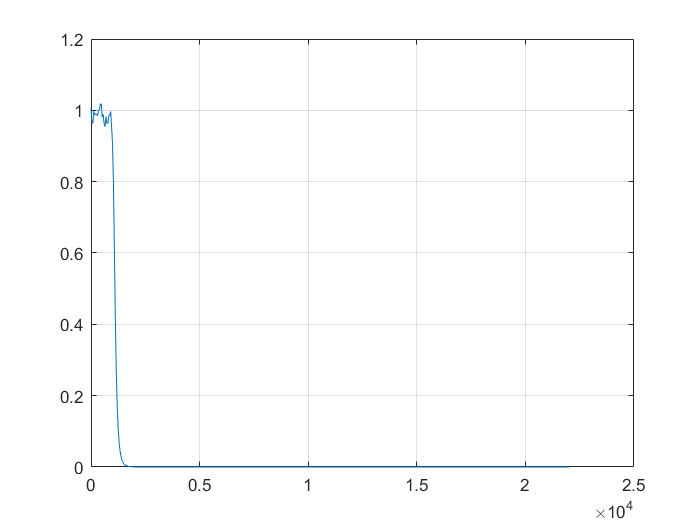

clear sound
timestart=0;
[audio,fs]=audioread('ech7.wav');%声音读取
audio = audio(:,1); %双通道变单通道
n=length(audio);
T = 1/fs;%采样间隔
t = (0:n-1)*T;%时间轴
f = (0:n-1)/n*fs;%频率轴
 %快速傅里叶变换
audio_fft=fft(audio,n)*T; 
timeend=t;
wlen=20480;%设置窗口长度。窗口越长时间分辨率越差，频率分辨率越好。
hop=2000;%每次平移的步长，最小为1。越小图像时间精度越好，但计算量大。
audio_fft=wkeep1(audio_fft,n+1*wlen);%中间截断

%设计IIR低通滤波器
rp = 1;
rs=60;
Ft=fs;
Fp=500;
Fs=900;                                        
wp=2*pi*Fp/Ft;
ws = 2*pi*Fs/Ft ;   %求出待设计的模拟滤波器的边界频率
[N,wn]=buttord(wp,ws,rp,rs,'s');    %低通滤波器的阶数和截止频率
[b,a]=butter(N,wn,'s');             %S域频率响应的参数即：滤波器的传输函数
[bz,az]=bilinear(b,a,0.5);          %利用双线性变换实现频率响应S域到Z域的变换
figure(2);%低通滤波器特性
[h,w]=freqz(bz,az);
title('IIR低通滤波器');
plot(w*fs/(2*pi),abs(h));
grid;

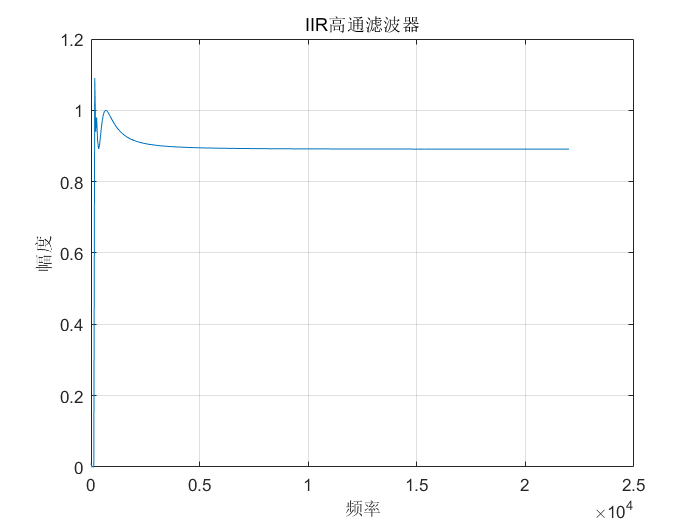


Fp=150;
Fs1=240;
Ft=fs;
As=100;
Ap=1;
wp=2*pi*Fp/Ft;
ws=2*pi*Fs1/Ft;
[n,wn]=ellipord(wp,ws,Ap,As,'s');
[b,a]=ellip(n,Ap,As,wn,'high','s');
[B,A]=bilinear(b,a,1);
[h,w]=freqz(B,A);
figure(4);
plot(w*Ft/pi/2,abs(h));
title('IIR高通滤波器');
xlabel('频率');
ylabel('幅度');
grid on;

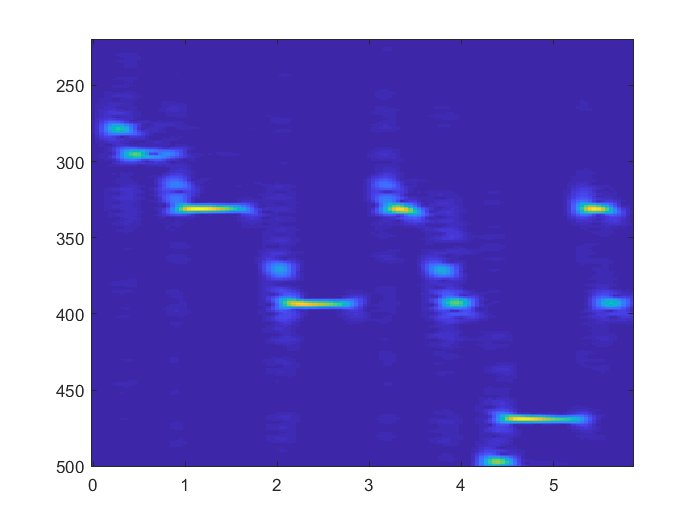


%滤波
z=filter(bz,az,audio);
z=filter(B,A,z);
z_fft=fft(z);     %滤波后的信号频谱
audiowrite('ech7_filter.wav',z,fs);
sound(z,fs);

%做短时傅里叶
h=hamming(wlen);%设置海明窗的窗长
f=220:1:500;%设置频率刻度

[tfr2,f,t2]=spectrogram(z,h,wlen-hop,f,fs,'MinThreshold',-1000,'reassigned','yaxis');

tfr2=tfr2*2/wlen*2;
figure

imagesc(t2+timestart-wlen/fs/2,f,abs(tfr2))


%imagesc(t2+timestart-wlen/fs/2,f,TF1);
shi=abs(tfr2)

shi =     0.0002    0.0001    0.0006    0.0011    0.0008    0.0013    0.0014    0.0013    0.0013    0.0010    0.0006    0.0001    0.0003    0.0004    0.0004    0.0003    0.0006    0.0009    0.0018    0.0024    0.0027    0.0025    0.0021    0.0014    0.0009    0.0006    0.0006    0.0005    0.0005    0.0004    0.0003    0.0003    0.0002    0.0001    0.0001    0.0003    0.0004    0.0005    0.0004    0.0002    0.0000    0.0000    0.0001    0.0005    0.0010    0.0013    0.0013    0.0010    0.0006    0.0003
    0.0003    0.0001    0.0006    0.0011    0.0011    0.0013    0.0015    0.0012    0.0011    0.0009    0.0009    0.0003    0.0005    0.0003    0.0005    0.0004    0.0004    0.0011    0.0019    0.0026    0.0029    0.0028    0.0024    0.0017    0.0013    0.0008    0.0005    0.0006    0.0004    0.0003    0.0002    0.0001    0.0001    0.0001    0.0002    0.0004    0.0004    0.0004    0.0004    0.0004    0.0003    0.0002    0.0003    0.0008    0.0011    0.0012    0.0010    0.0007    0.0004   

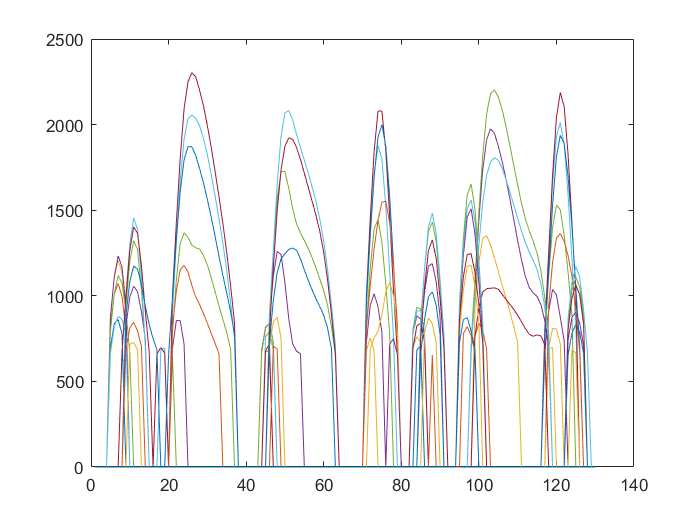


clims = [50 100];

shi=shi.*10000;
shi(shi<650)=0;
plot(shi');

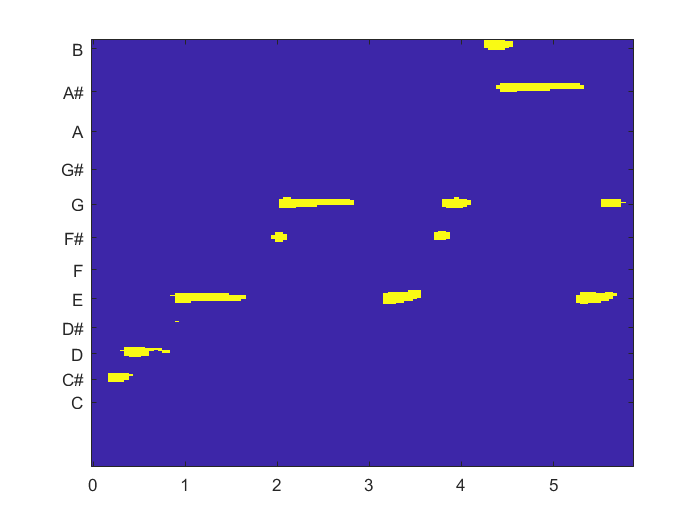

imagesc(t2+timestart-wlen/fs/2,f,shi,clims);
axis xy; 
set(gca,'ytick',[262 277 294 311 330 349 370 392 415 440 466 494]);
set(gca,'yticklabel',{'C','C#','D','D#','E','F','F#','G','G#','A','A#','B'});

%TG = islocalmax(shi','FlatSelection', 'first')
%TF = islocalmax(shi,'MinSeparation',3,'SamplePoints',t);
%TF = islocalmax(shi,'FlatSelection', 'all')
%p=TF.*shi.*TG'

%TG2 = islocalmax(p,1)
%plot(p');
%imagesc(t2,f,TF);
%xlswrite('12.xlsx',shi)
%for a=0:+0.1:t2

%end
[y,fs1]=audioread('ech7_filter.wav');
audioinfo('ech7_filter.wav')

ans = 包含以下字段的 struct :
             Filename: 'D:\OneDrive - bjtu.edu.cn\ISEP\A2\IG 2307 2407 signal processing\SAP项目\pianoSoundFiles\ech7_filter.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 278903
             Duration: 6.3243
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


audiowrite('ech7_final_watermark.wav',z,fs1,'BitsPerSample',16,'Comment','This is my new audio file.','Title','Final','Artist','zhouyu');
audioinfo('ech7_final_watermark.wav')

ans = 包含以下字段的 struct :
             Filename: 'D:\OneDrive - bjtu.edu.cn\ISEP\A2\IG 2307 2407 signal processing\SAP项目\pianoSoundFiles\ech7_final_watermark.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 278903
             Duration: 6.3243
                Title: 'Final'
              Comment: 'This is my new audio file.'
               Artist: 'zhouyu'
        BitsPerSample: 16
